# ECSE403Lab2

% Question 1
Jm=0.01;
b=0.001;
Ke=0.02;
Kt=0.02;
Ra=10;

s=tf('s');

H2 = (Kt/Ra)/(Jm*s^2+(b+Kt*Ke/Ra)*s)


H2 =
 
         0.002
  --------------------
  0.01 s^2 + 0.00104 s
 
Continuous-time transfer function.



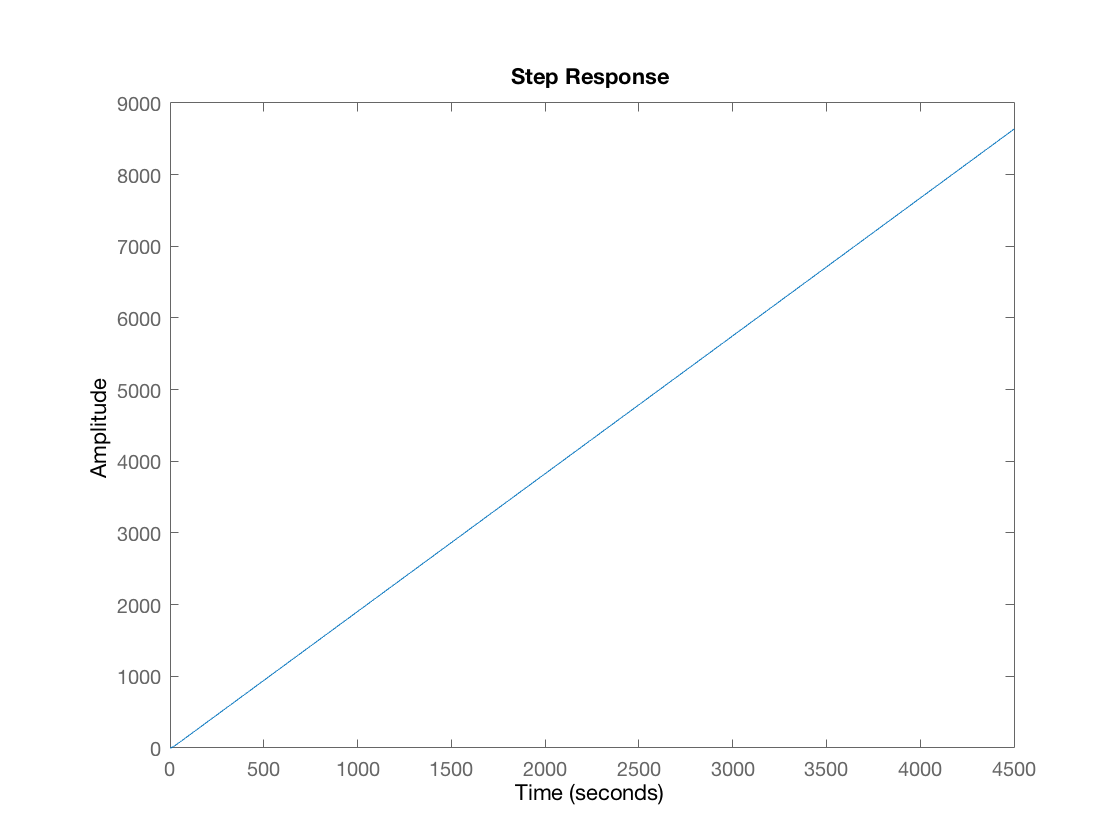

stepplot(H2)

stepinfo(H2)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


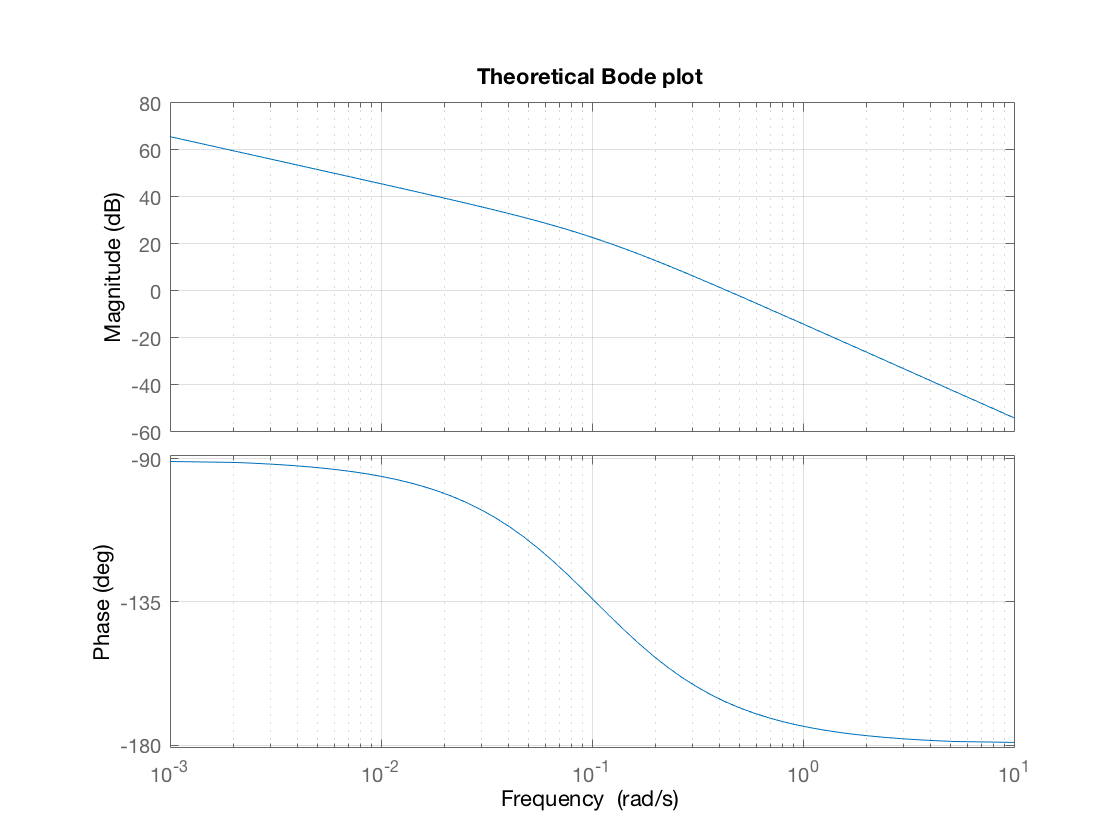


% Question 3
%theoretical bode plots
bode(H2)
title('Theoretical Bode plot')
grid on

%Bode plot from the experiments
w=[0.1 1 10 100 1000];
Freq=log10(w)

Freq =     -1     0     1     2     3


G2=[14 0.154 1.685e-3 1.6115e-5 1.593e-7]

G2 =    14.0000    0.1540    0.0017    0.0000    0.0000


Gain2=20*log10(G2)

Gain2 =    22.9226  -16.2496  -55.4680  -95.8554 -135.9557


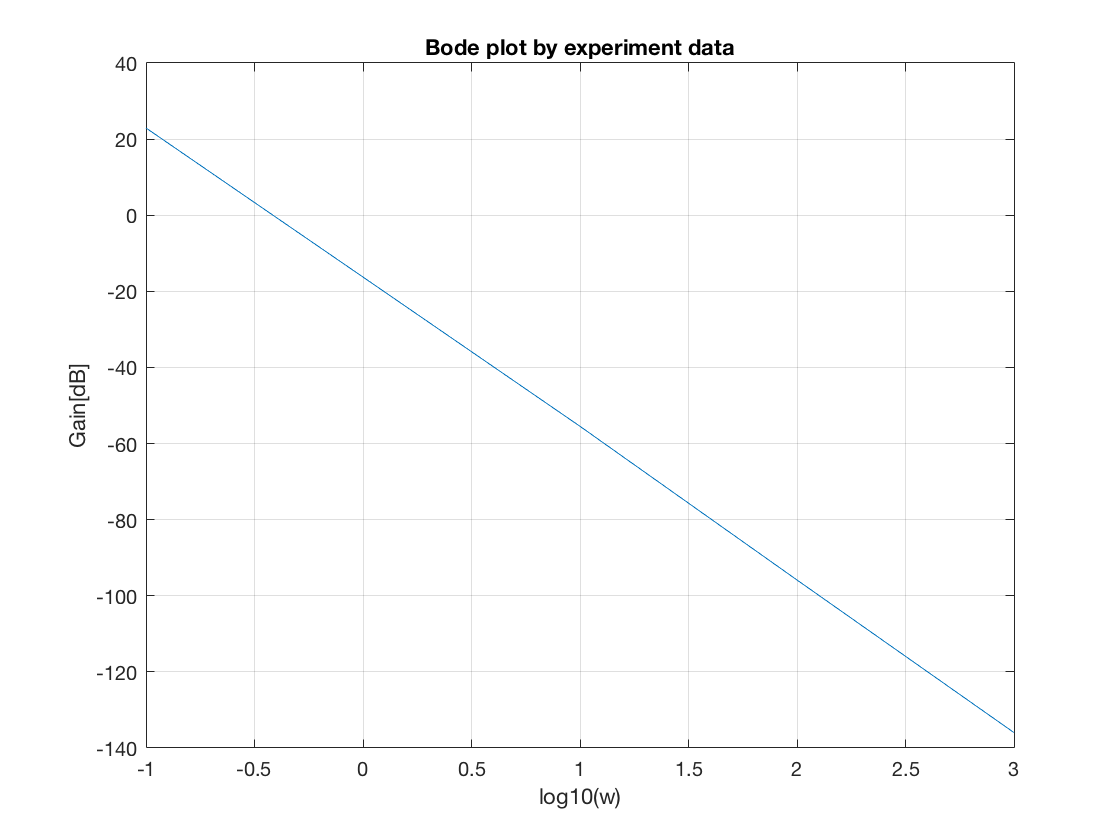

plot(Freq, Gain2)
title("Bode plot by experiment data")
xlabel('log10(w)')
ylabel("Gain[dB]")
grid on


%Question 4 
H4 = H2/(1+H2)


H4 =
 
                  2e-05 s^2 + 2.08e-06 s
  ------------------------------------------------------
  0.0001 s^4 + 2.08e-05 s^3 + 2.108e-05 s^2 + 2.08e-06 s
 
Continuous-time transfer function.



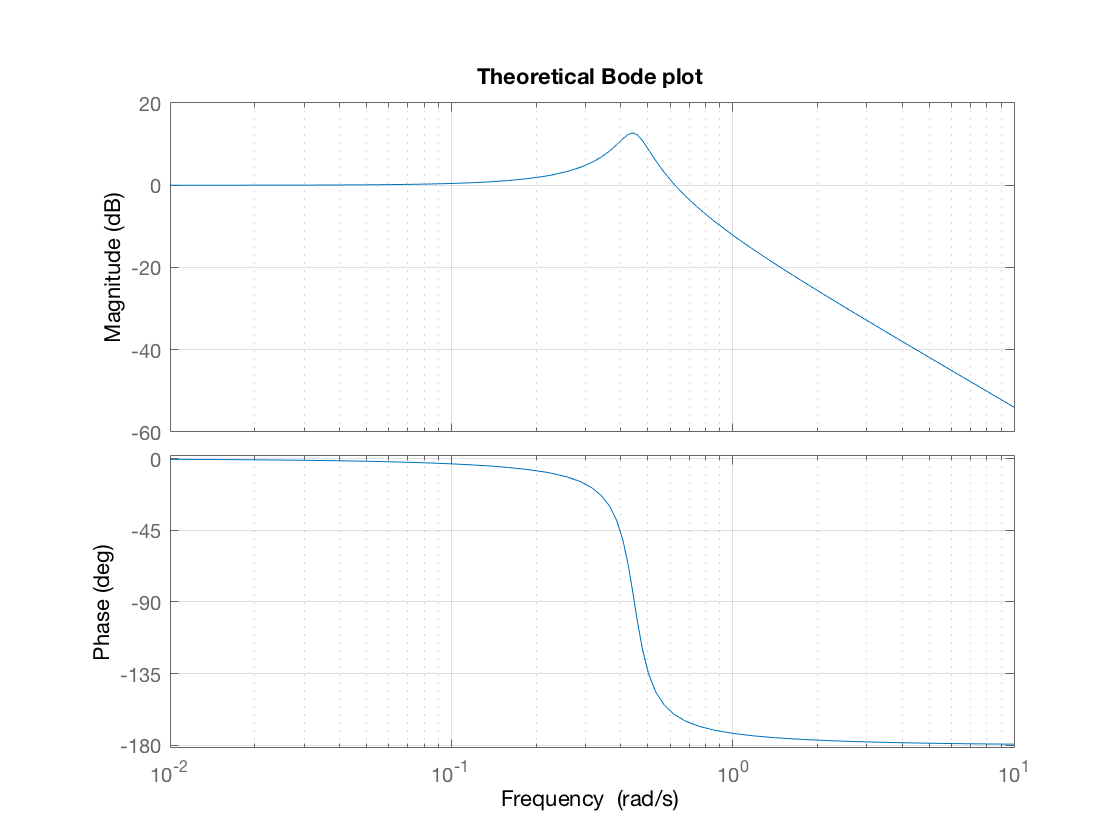

bode(H4)
title('Theoretical Bode plot')
grid on

%Bode plot from the experiments
w=[0.1 1 10 100 1000];
Freq=log10(w)

Freq =     -1     0     1     2     3


G4=[1.05 2.477e-1 1.882e-3 1.561e-5 1.507e-7]

G4 =     1.0500    0.2477    0.0019    0.0000    0.0000


Gain4=20*log10(G4)

Gain4 =     0.4238  -12.1215  -54.5076  -96.1319 -136.4377


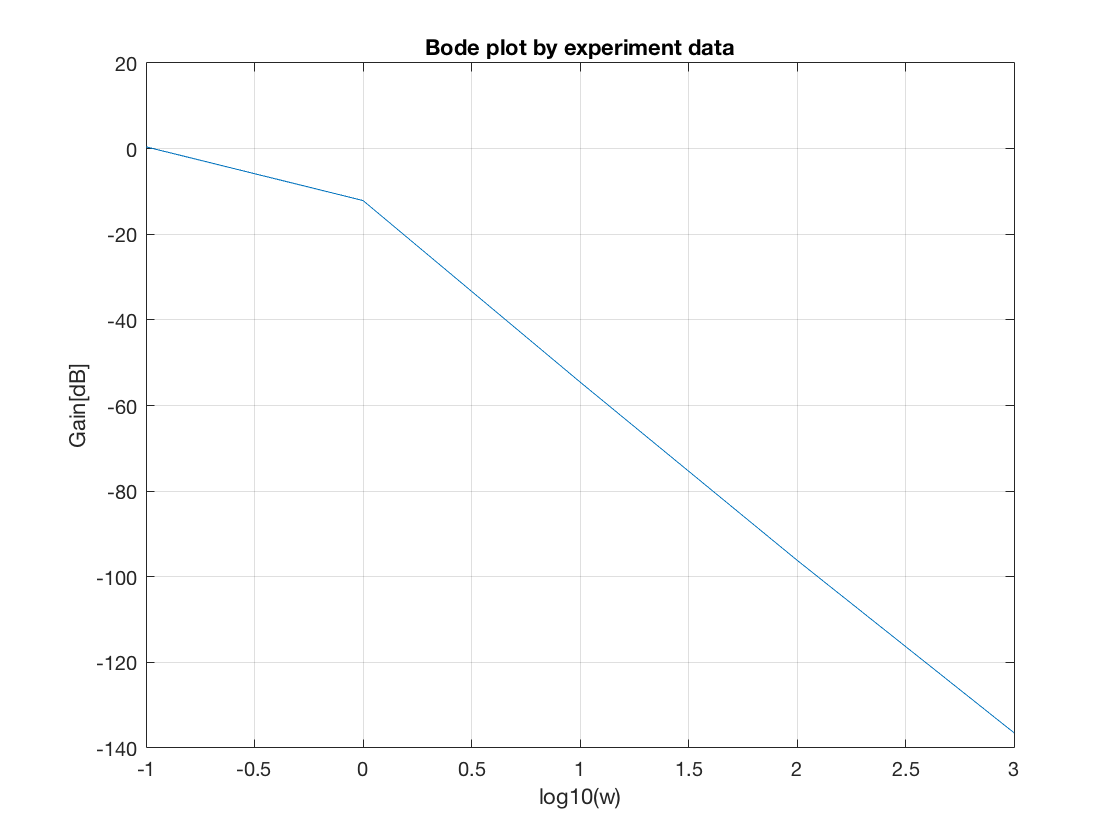

plot(Freq, Gain4)
title("Bode plot by experiment data")
xlabel('log10(w)')
ylabel("Gain[dB]")
grid on